## Семинар 14. Теорема Экхарта-Янга и сжатие изображений

#### Теорема Экхарта-Янга:

Пусть $A_k =  \sum_{i=1}^k [\sigma_i  \vec{u}_i \vec{v}_i^T]$, где $\forall $ $k\le m$, тогда для $\forall $ матрицы $B$ ранга $k$:  $||A-B||\ge||A-A_k||$.

Иными словами, матрица $A_k$ является наилучшей аппроксимацией матрицы $A$ среди всех матриц ранга $k$.

Картинка  - это же матрица!

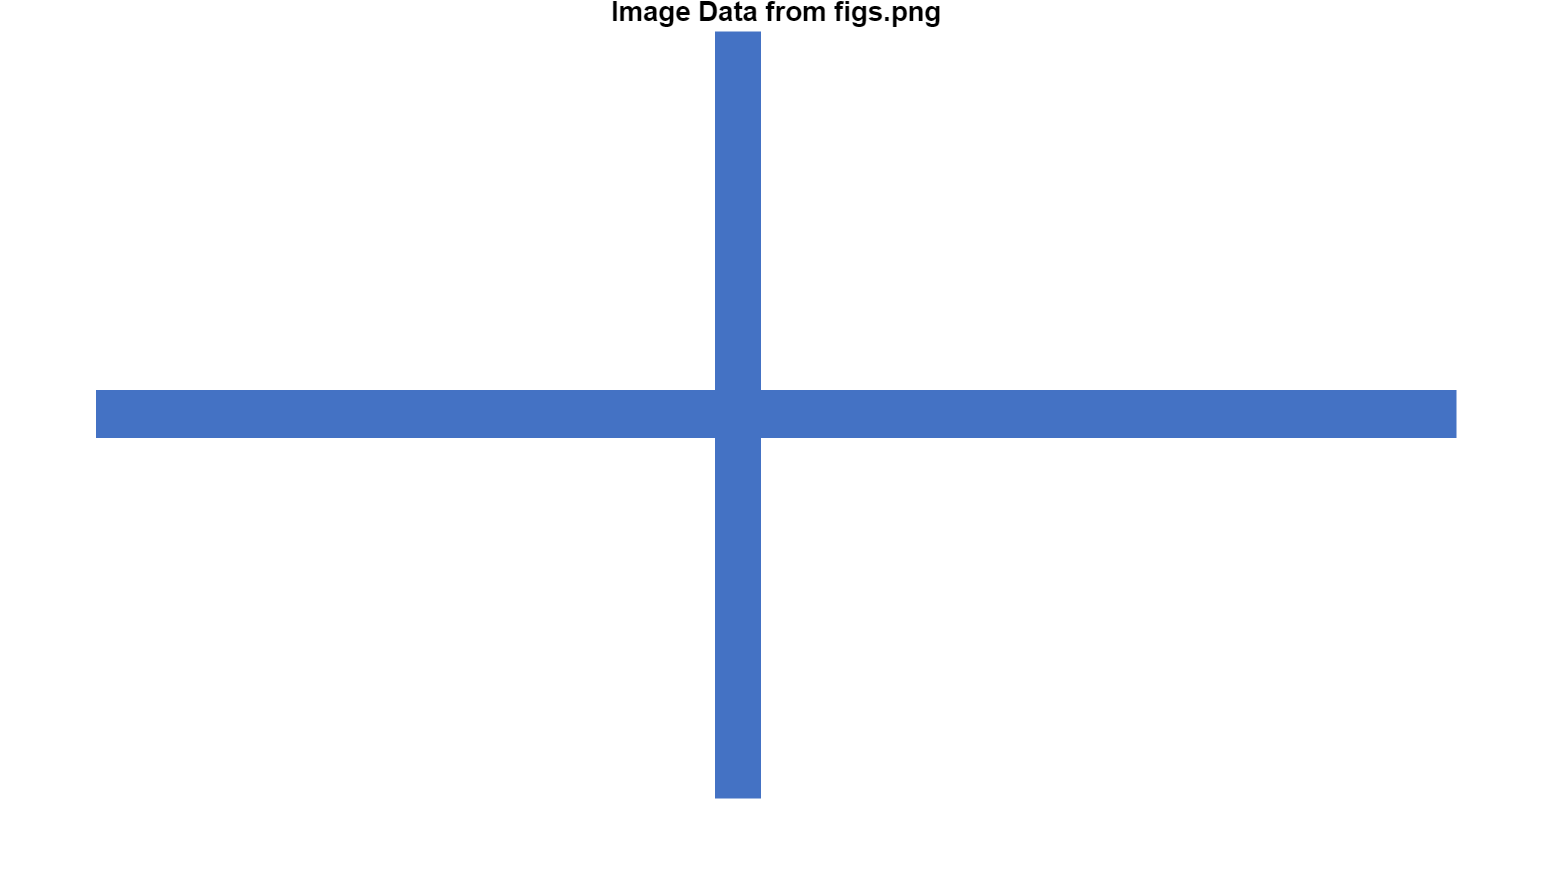

clearvars
% Import image
folder =  get_folder();
selected_image= "cross.png";
figs_folder =folder + "\figs"; 
full_file = fullfile(figs_folder,selected_image);
figs = imread(full_file);

% Display results
imshow(figs);
title("Image Data from figs.png");

 
A = double((im2gray(figs))); 
[U,S,V] = svd(A);% сингулярное разложение исходной картинки

 
number_of_dimentions=24; % ранг матрицы Ak
if number_of_dimentions>size(U,2)
    number_of_dimentions = size(U,2);
end
% уменьшаем размерность исходной картинки
Uk = U(:,1:number_of_dimentions);
Sk = diag(S(1:number_of_dimentions,1:number_of_dimentions));
Vk = V(:,1:number_of_dimentions);
Ak = Uk.*Sk'*Vk'; % матрица уменьшенной размерности 
disp("Слева-сжатая, справа - исходная:")

Слева-сжатая, справа - исходная:


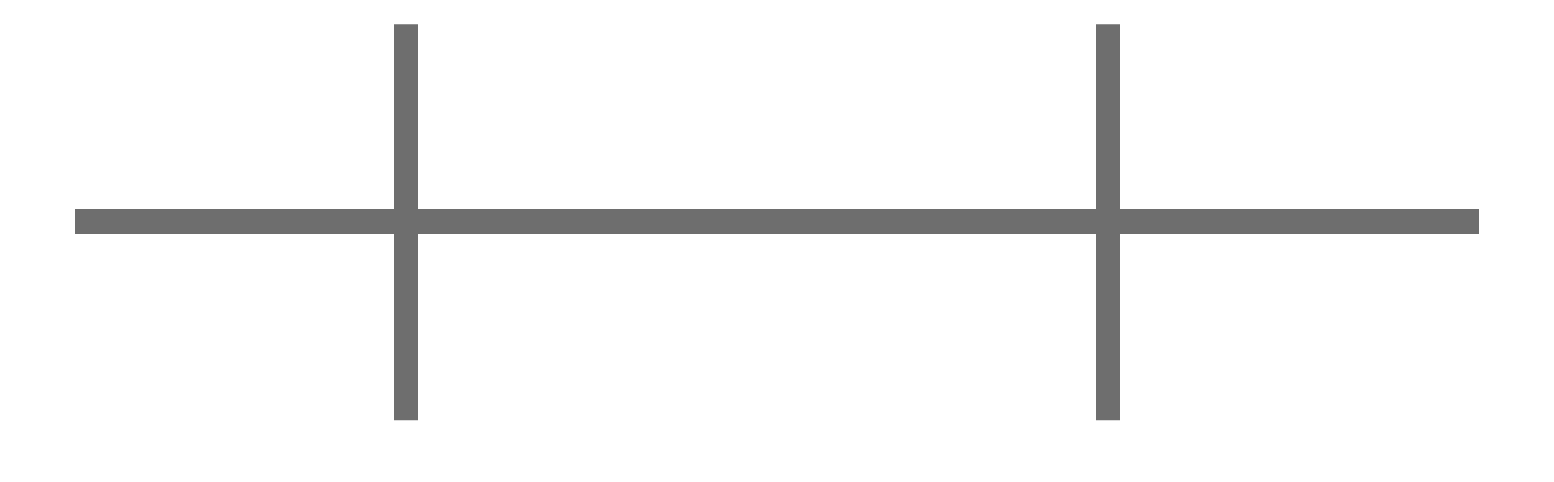

imshow(uint8([Ak,A]))

display("Ранг исходной картинки:" + rank(A))

    "Ранг исходной картинки:2"



display("Ранг сжатой картинки:" + rank(Ak))

    "Ранг сжатой картинки:2"



wA  = mem_size_summ("A") ;% объем памяти в байтах,занимаемой исходной матрицей
wAk = mem_size_summ("Uk","Sk","Vk") ; % объем памяти в байтах
disp("Объем исходной матрицы в байтах :"+ wA)

Объем исходной матрицы в байтах :7156800


disp("Объем сжатой матрицы  в байтах :"+wAk)

Объем сжатой матрицы  в байтах :378432



disp("Относительный объем памяти сжатый/несжатый:"+ wAk/wA)

Относительный объем памяти сжатый/несжатый:0.052877


#### Спектр сингулярных значений

ax = get_next_ax();

fig1


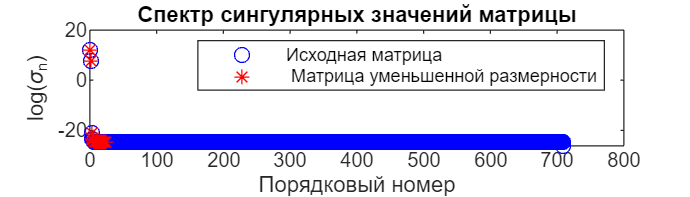

plot(ax,1:size(S,2),log(sum(S)),'ob',1:number_of_dimentions,log(Sk),'*r')
title(ax,"Спектр сингулярных значений матрицы");
xlabel(ax,"Порядковый номер");
ylabel(ax,"log(\sigma_n)");
legend(ax,["Исходная матрица" " Матрица уменьшенной размерности"]);

#### Спектр сингулярных значений как "признак" матрицы

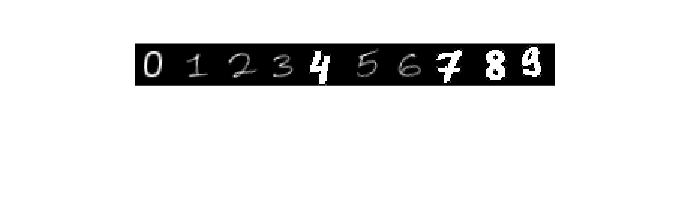

ranks =     14    13    19    14    16    15    16    20    15    15


fig2


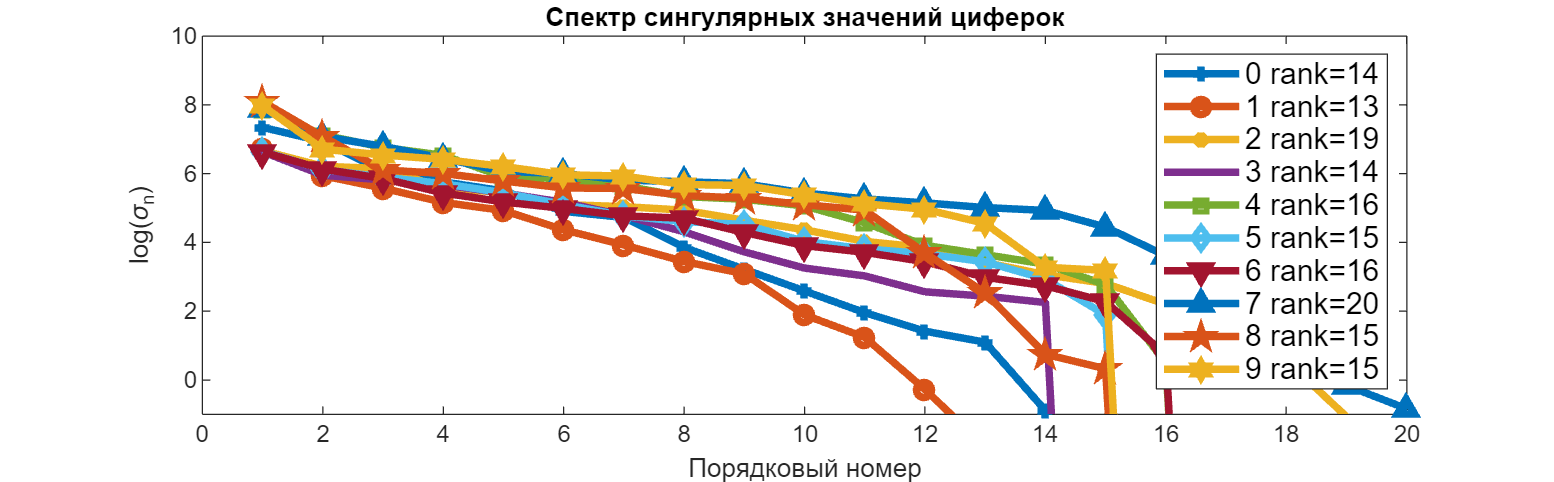

% загружаем картинки написанных от руки цифр и пытаемся сравнить спектры их
% сингулярных значений
check_numbers_flag = true;
if check_numbers_flag
    
    path = get_folder + "\figs\";
    svd_struct(10) = struct("V",[],"S",[],"U",[],"M",[]);
    for ii=0:9
        cur_im = imread(fullfile(path,ii+".png"));
        mat = double((im2gray(cur_im)));
        i = ii +1;
        svd_struct(i).M = (mat);
        [svd_struct(i).V,svd_struct(i).S,svd_struct(i).U] = svd(mat);
    end
    imshow(uint8([svd_struct(:).M]))
    ranks = arrayfun(@(X)rank(X.M),svd_struct)
    sig_mat = ones(size(mat,1),10); % матрица спектров сингулярных значений
    for iii = 1:numel(svd_struct)
        sig_mat(:,iii) = sum(svd_struct(iii).S);
    end
    p = plot(get_next_ax(),log(sig_mat), 'LineWidth',3,'MarkerSize',6);
    ylim([-1,10])
    legend(string(0:9) + " rank=" + string(ranks),'FontSize',12);
    mark = ["+","o","*",".","square","diamond","v","^","pentagram","hexagram"];
    arrayfun(@(ii)set(p(ii),"Marker",mark(ii)),1:10);
    title("Спектр сингулярных значений циферок");
    xlabel("Порядковый номер");
    ylabel("log(\sigma_n)");
end

function ax = draw_vector(ax,ttl,names,type,varargin)
% функция строит двух- и трех-мерные вектора, а также рассеянные данные из
% матрицы
% ax - оси (если пустые, то создаются новые)
% ttl - заголовок картинки
% names - имена векторов
% type:
%       "vector" - аргументы, которые передаются после интерпретируются
%                   как отдельные вектора
%       "point"  - в этом случае передается матрица в качестве аргумента и
%       столбцы матрицы строятся при помощи функций scatter и scatter3 d
%       в зависимости от размерности массива
    arguments
        ax =[]
        ttl string =strings(0,1)
        names string =strings(0,1)
        type string {mustBeMember(type,["vector" "point"])}="vector"
    end
    arguments (Repeating)
        varargin double
    end
    was_empty = isempty(ax); % это признак того, что все строится на новых осях
    if was_empty
        ax = get_next_ax();
    else
        hold(ax,"on");
        % if ~isempty(ax.Legend)
        %     leg_before = ax.Legend.String;
        % else
        %     leg_before = strings(0,1);
        % end
    end
    
    if strcmp(type,"vector")
        is_3D = numel(varargin{1})==3;
            if is_3D
                [x,y,z]  = make_xy(varargin{1});
                plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y,z] = make_xy(varargin{iii});
                        plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off                
            else
                [x,y]  = make_xy(varargin{1});
                plot(ax,x,y,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y]  = make_xy(varargin{iii});
                        plot(ax,x,y,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off
            end
            if isempty(names)||(numel(names)~=numel(varargin))
                legend(ax,string(1:numel(varargin)));
                
            else
                % if ~was_empty
                %      names= [names(:);leg_before(:)];
                % end
                legend(ax,names);
            end
            xlim(ax,[-1 1]);
            ylim(ax,[-1 1]);
            if ~isempty(ttl)
                title(ax,ttl);
            end
    else
        %data_number = numel(varargin); % число массивов данных
        is_3D = numel(varargin)==3;
        data = varargin{1};
        if size(data,2)>1
            data = transpose(data);
            is_transpose = true;
        else
            is_transpose = false;
        end
        if ~is_transpose
            for iii = 2:numel(varargin)
                data = [data,varargin{iii}];
            end
        else
            for iii = 2:numel(varargin)
                data = [data,transpose(varargin{iii})];
            end            
        end

        if is_3D
            scatter3(ax,data(:,1),data(:,2),data(:,3));
        else
            scatter(ax,data(:,1),data(:,2));
        end

    end
    if ~was_empty
            hold(ax,"off");
    end
end
function [x,y,z]  = make_xy(col)
% добавляет к координатам вектора нули так, чтобы при помощи функции plot
% строилась линия
    switch numel(col)
        case 1
            x = [col(1)];
            y = 0;
            z = 0;
        case 2
            x = [0 col(1)];
            y = [0 col(2)];
            z = zeros(1,2);
        case 3
            x = [0 col(1)];
            y = [0 col(2)];
            z = [0 col(3)];
    end
end
function [bpar,bper,ang] = projection_matrix(A,b)
% функция считает угол между вектором и пространством столбцов матрицы A
    for ii =1:size(A,2)
        A(:,ii) = A(:,ii)/norm(A(:,ii));
    end
    beta = A*transpose(A)*b;
    beta = beta/norm(beta); % нормируем вектор beta
    Pbeta = beta*transpose(beta); % оператор проектирования вектора на 
    bpar = Pbeta*b;
    bper = b-bpar;
    ang = rad2deg(acos(norm(bpar)/norm(b)));
end
function [new_ax,fig_handle] = get_next_ax(index)
% функция, которая возвращает новые оси на новой фигуре
    arguments
        index = []
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);
        clf(fig_handle);
        new_ax = axes(fig_handle);
        disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle);    
    end
end
function mem_size = mem_size_summ(varargin)
% функция считает объем несокльких переменных в памяти base workspace
    names = string(varargin);
    mem_size = 0;
    base_vars = evalin("base","whos");
    flag = arrayfun(@(X)any(strcmp(X.name,names)),base_vars);
    if ~any(flag)
        return
    end
    mem_size = sum(arrayfun(@(X)X.bytes,base_vars(flag)));
end
function folder = get_folder()
% текущая папка
folder = fileparts(matlab.desktop.editor.getActiveFilename);
end